# M E 325 Supplemental Homework 1

## Objective:

Reinforce the parameters that influence the fatigue life of a part and to determine the mean and alternating von Mises stresses for determination of a factor of safety using the Goodman and Langer failure envelopes.

### Determine:

- The theoretical stress concentration factor, $K_t$, using the link below

[https://efatigue-dev.altair.mediag.com](https://efatigue-dev.altair.mediag.com) 

- Notch sensitivity values, $q=\frac{1}{1+\frac{\sqrt{a}}{\sqrt{r}}}$

- Fatigue stress concentration factors, $K_f =q\left(K_t -1\right)+1$

- Adjusted stress values accounting for stress risers in geometry

- Mean and alternating von Mises stresses, $\sigma_m^{\prime } ,\sigma_a^{\prime }$

- Fatigue strength, $S_f$, at a specified number of stress cycles, $N$. $S_f =AN^b$

- Factor of safety against fatigue and yielding using the Goodman and Langer failure envelopes.

### Given Data:

$D=2\ldotp 0\mathrm{in}$, $d=1\ldotp 75\mathrm{in}$, $r=0\ldotp 25\mathrm{in}$, $S_{\mathrm{ut}} =90\mathrm{kpsi}$, $S_y =75\mathrm{kpsi}$

D = 2

D = 2

d = 1.75

d = 1.7500

r = 0.25

r = 0.2500

S_ultimate = 90

S_ultimate = 90

S_yield = 75

S_yield = 75

#### Question 1:

The round shaft shown below has a U-shpaed groove milled around its perimeter. The major diameter, $D$, is 2.0in, the minor diameter, $d$, is 1.75in, and the groove around the radius, $r$, of 0.25in. For the loadings shown, what is the theoretical stress concentration factor, $K_t$?

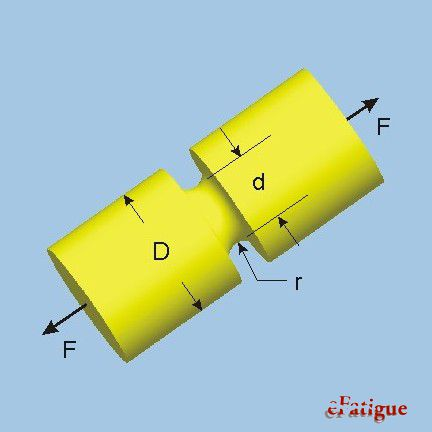

Utilizing the website linked in the problem statement:


$$K_t =1\ldotp 94$$


K_t = 1.94

K_t = 1.9400

An associated Peterson Plot has been added below showing the calculation:

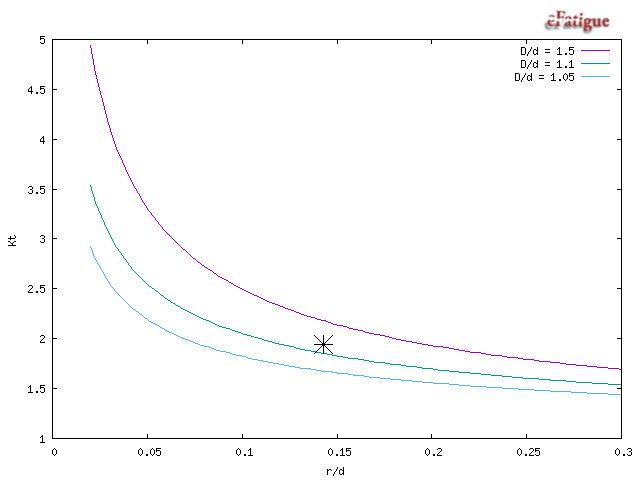

#### Question 2:

If the ultimate tensile strength for this component is 90 kpsi, what is the value of the fatigue stress concentration factor, $K_f$?

The fatigue stress concentration factor, $K_f$, is represented by


$$K_f =q\left(K_t -1\right)+1$$


where $q$ is the notch sensitivity and $K_t$ is the stress concentration factor. The notch sensitivity, $q$, is represented by


$$q=\frac{1}{1+\frac{\sqrt{a}}{\sqrt{r}}}$$


where $\sqrt{a}$ is the Neuber's constant and $r$ is the notch radius. In the case of tensile loading, the equation for Neuber's constant, $\sqrt{a}$, is the following:


$$\sqrt{a}=0\ldotp 246-3\ldotp 08\left({10}^{-3} \right)S_{\mathrm{ut}} +1\ldotp 51\left({10}^{-5} \right)S_{\mathrm{ut}}^2 -2\ldotp 67\left({10}^{-8} \right)S_{\mathrm{ut}}^3$$


for $50\le S_{\mathrm{ut}} \le 250\mathrm{kpsi}$. 

Find Neuber's contstant, $\sqrt{a}$:

neuber = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3

neuber = 0.0716

We find Neuber's constant for this specimen to be $0\ldotp 0716\;{\mathrm{in}}^{\frac{1}{2}}$.

Find notch sensitivity, $q$:

q = 1/(1 + (neuber/sqrt(r)))

q = 0.8747

We find the notch sensitivity to be $0\ldotp 8747$.

Subbing in $q$:

K_f = q*(K_t-1)+1

K_f = 1.8222

We find the fatigue stress concentration factor to be $1\ldotp 8222$.

#### Question 3:

If the ultimate tensile strength for this component is 90kpsi, what is the value of the fatigue stress concentration factor, $K_f$, if the shaft is loaded as indicated in the accompanying picture?

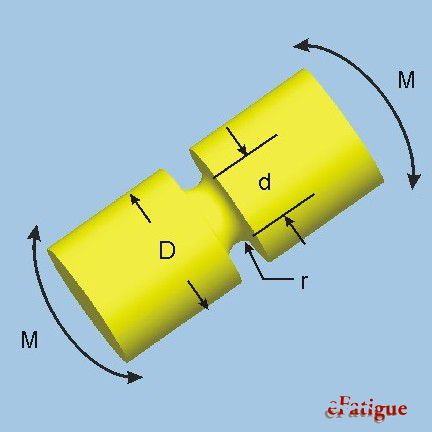

This specimen is loaded with a bending moment. As before, the stress concentration factor, $K_t$, is calculated from the eFatigue website. Inputing the data into the website, we find:


$$K_t =1\ldotp 7$$


K_t = 1.7

K_t = 1.7000

An associated Peterson Plot has been added below showing the calculation:

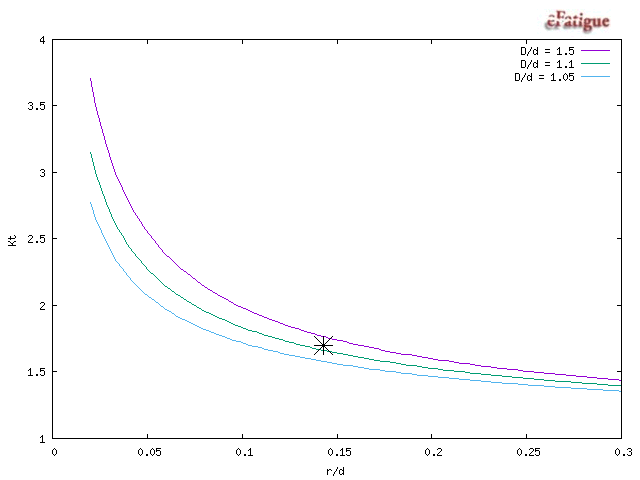

In the case of bending, we calculate Neuber's constant with the same equation as the last question

neuber = 0.246-3.08*(10^-3)*S_ultimate+1.51*(10^-5)*S_ultimate^2-2.67*(10^-8)*S_ultimate^3

neuber = 0.0716

The notch sensitivity is calculated in the same manner as well:

q = 1/(1 + (neuber/sqrt(r)))

q = 0.8747

And finally, the fatigue stress concentration factor, $K_f$, is calculated:

K_f = q*(K_t-1)+1

K_f = 1.6123